M=Model(false);%Create model without robot
in = zeros(1,4);%declaring in
in(1)=185;
in(2)=170;
in(3)=70;
in(4)=0;
out=M.robot.step2ik(in(1:3),in(4))%run the inverse kinimatics

out =    42.5805   32.9015   43.9687  -76.8702


figure;%reset the plot before a new plot is made
result=M.plot_arm(out)%plot the result of running the forward kinimatics of the output of the inverse kinimatics

result =     0.7363   -0.0000   -0.6766  185.0000
    0.6766   -0.0000    0.7363  170.0000
   -0.0000   -1.0000    0.0000   70.0000
         0         0         0    1.0000


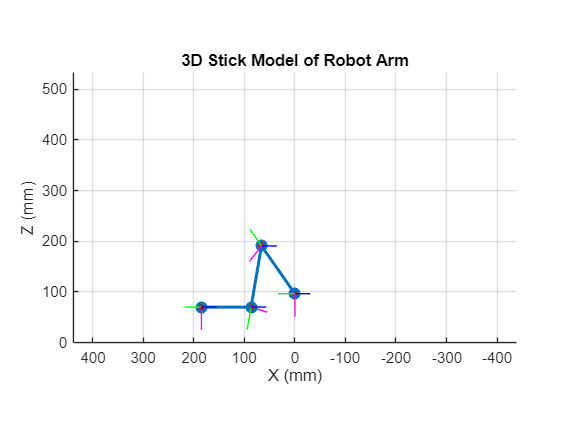

hold on;
plot3(in(1),in(2),in(3),'.','MarkerSize',10); %plot desired endpoint to compare with the resulting endpoint 

ee=result(1:3,4)' %get the end effector position out of the resulting transformation matrix

ee =   185.0000  170.0000   70.0000


error=ee-in(1:3) %compare the resulting end effector position with the desired end effector position

error = 1.0e-12 *

         0   -0.0284   -0.1705


errorNorm=norm(error) 

errorNorm = 1.7288e-13

Test new IK

NewOut=M.robot.step2ik2(in(1:3),in(4))

NewOut =    42.5805   32.9015   43.9687  -76.8702


NewResult=M.fk(NewOut);
NewEE=NewResult'

NewEE =   185.0000
  170.0000
   70.0000


NewError=NewEE'-in(1:3)

NewError = 1.0e-09 *

   -0.2994   -0.2751    0.3861


NewErrorNorm=norm(NewError)

NewErrorNorm = 5.6072e-10

Time test

tic;
out=M.robot.step2ik(in(1:3),in(4));

Unable to resolve the name 'M.robot.step2ik'.

oldTime=toc;
tic;
NewOut=M.robot.step2ik2(in(1:3),in(4));
newTIme=toc;
disp(oldTime)
disp(newTIme)

FK test

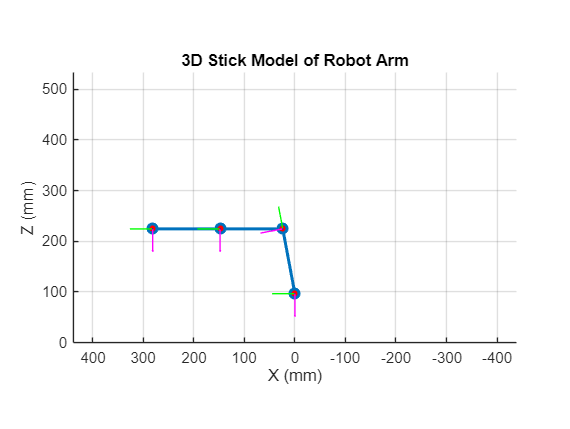

result =     1.0000         0         0  281.3999
   -0.0000    0.0000    1.0000   -0.0000
         0   -1.0000    0.0000  224.3254
         0         0         0    1.0000


M=Model(false);%Create model without robot
in = zeros(1,4);%declaring in
in(1)=0;
in(2)=0;
in(3)=0;
in(4)=0;
figure;
view(3)
result=M.plot_arm(in)%plot the result of running the forward kinimatics of the output of the inverse kinimatics